# Representational Similarity Analysis tutorial

Author: Choong-Wan Woo (Sungkyunkwan University) [https://cocoanlab.github.io/](https://cocoanlab.github.io/)

Date: 2019/8/17 @ KHBM 2019 Summer school

## Dataset

- from Woo et al., 2014, Nat Comms (download: [https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf](https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf))

- N = 59

- There were two types of tasks, and in each task, there were two conditions (2 x 2 design)

- -- Physical pain task (Heat, Warmth conditions)

- -- Social pain task (Rejection, Friends conditions)

## Analysis plan

- Computing RDMs for each participant, for each region (4 ROIs: aINS, dACC, S2/dpINS, TPJ),  and visualize the RDMs

- Comparing brain and model RDMs: We have two model RDMs: physical vs. social, aversive vs. non-aversive, and 4 ROIs

- Statistical inference: Using the neurosync mask that Woo 2014 used, we will do statistical inference

## Step 1: Computing and visualizing RDMs

% read images
basedir = '/Users/clinpsywoo/Dropbox/github/khbm2019_RSA_tutorial/tutorial';
% you need to change the first part of the path into your path directories

datdir = fullfile(basedir, 'data', 'contrast_images');

roi_masks = filenames(fullfile(basedir, 'masks', '*smooth_mirror.nii'));
whole_masks = filenames(fullfile(basedir, 'masks', '*Woo2014.nii'), 'char');
% filenames is a useful function from CanlabCore toolbox

conditions = {'heat', 'warmth', 'rejection', 'friend'};

line = repmat('=', 1, 50); % for display

for i = 1:numel(roi_masks)
    [~, roi{i}.name] = fileparts(roi_masks{i});
    disp(line);
    fprintf('Reading data from %s\n', roi{i}.name);
    disp(line);
    roi{i}.heat = fmri_data(filenames(fullfile(datdir, 'heat_sub_*.nii')), roi_masks{i});
    roi{i}.warmth = fmri_data(filenames(fullfile(datdir, 'warmth_sub_*.nii')), roi_masks{i});
    roi{i}.rejection = fmri_data(filenames(fullfile(datdir, 'rejection_sub_*.nii')), roi_masks{i});
    roi{i}.friend = fmri_data(filenames(fullfile(datdir, 'friend_sub_*.nii')), roi_masks{i});
end

Reading data from S2_dpINS_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.233853초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.260482초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.232150초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.238006초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from aINS_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.228889초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.266703초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.248521초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.263496초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from dACC_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.233997초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.252351초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.255809초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.266063초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from tpj_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.267580초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.288385초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.275797초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.291910초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


% Reading data for whole-brain mask
for cond_i = 1:numel(conditions)
    [~, whole.name] = fileparts(whole_masks);
    disp(line);
    fprintf('Reading data from the whole-brain mask for %s\n', conditions{cond_i});
    disp(line);
    eval(['whole.' conditions{cond_i} ' = fmri_data(filenames(fullfile(datdir, ''' conditions{cond_i} '_sub_*.nii'')), whole_masks);']);
end

Reading data from the whole-brain mask for heat


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.398826초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for warmth


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.380220초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for rejection


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.427094초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from the whole-brain mask for friend


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.438862초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


### Computing RDMs for each region and for each individual

n_subj = size(roi{1}.heat.dat,2);

for roi_i = 1:numel(roi)
    roi{roi_i}.rdms = zeros(4,4);
    for cond_i = 1:numel(conditions)
        for cond_j = 1:numel(conditions)
            if cond_i ~= cond_j
                for subj_i = 1:n_subj

                    eval(['roi{roi_i}.rdms(cond_i,cond_j,subj_i) = 1-corr(roi{roi_i}.' ...
                        conditions{cond_i} '.dat(:,subj_i), roi{roi_i}.' ...
                        conditions{cond_j} '.dat(:,subj_i));']);
                    
                    roi{roi_i}.rdms(cond_j,cond_i,subj_i) = roi{roi_i}.rdms(cond_i,cond_j,subj_i); % to make RDMs symmetric
                    
                end
            end
        end
    end
end

for cond_i = 1:numel(conditions)
    for cond_j = 1:numel(conditions)
        if cond_i ~= cond_j
            for subj_i = 1:n_subj
                eval(['whole.rdms(cond_i,cond_j,subj_i) = 1-corr(whole.' ...
                    conditions{cond_i} '.dat(:,subj_i), whole.' ...
                    conditions{cond_j} '.dat(:,subj_i));']);
                
                whole.rdms(cond_j,cond_i,subj_i) = whole.rdms(cond_i,cond_j,subj_i); % to make RDMs symmetric
            end
        end
    end
end


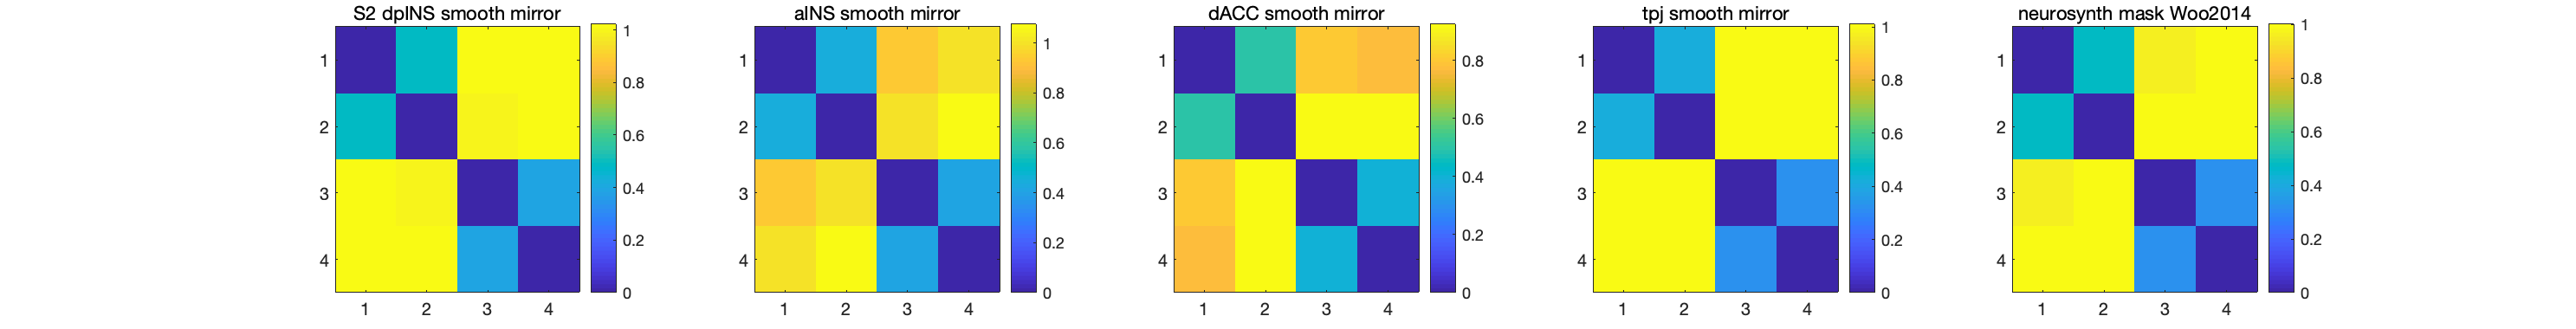

% visualize mean rdms
figure;
set(gcf, 'position', [1         765        1487         190])
for i = 1:5
    subplot(1,5,i);
    if i ~= 5
    imagesc(mean(roi{i}.rdms,3));   
    colorbar;
    roi{i}.name(strfind(roi{i}.name, '_')) = ' ';
    title(roi{i}.name);
    else
        imagesc(mean(whole.rdms,3));   
        colorbar;
        whole.name(strfind(whole.name, '_')) = ' ';
        title(whole.name);        
    end
end

## Step 2: Comparing brain and model RDMs

## Step 3: Statistical inference